# F20 Eksamenssæt

## Opgave 1

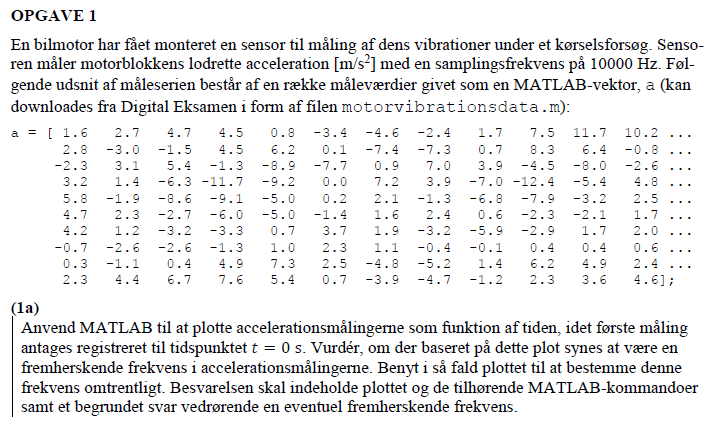

a = [ 1.6   2.7   4.7   4.5   0.8  -3.4  -4.6  -2.4   1.7   7.5  11.7  10.2 ...
      2.8  -3.0  -1.5   4.5   6.2   0.1  -7.4  -7.3   0.7   8.3   6.4  -0.8 ...
     -2.3   3.1   5.4  -1.3  -8.9  -7.7   0.9   7.0   3.9  -4.5  -8.0  -2.6 ...
      3.2   1.4  -6.3 -11.7  -9.2   0.0   7.2   3.9  -7.0 -12.4  -5.4   4.8 ...
      5.8  -1.9  -8.6  -9.1  -5.0   0.2   2.1  -1.3  -6.8  -7.9  -3.2   2.5 ...
      4.7   2.3  -2.7  -6.0  -5.0  -1.4   1.6   2.4   0.6  -2.3  -2.1   1.7 ...
      4.2   1.2  -3.2  -3.3   0.7   3.7   1.9  -3.2  -5.9  -2.9   1.7   2.0 ...
     -0.7  -2.6  -2.6  -1.3   1.0   2.3   1.1  -0.4  -0.1   0.4   0.4   0.6 ...
      0.3  -1.1   0.4   4.9   7.3   2.5  -4.8  -5.2   1.4   6.2   4.9   2.4 ...
      2.3   4.4   6.7   7.6   5.4   0.7  -3.9  -4.7  -1.2   2.3   3.6   4.6];


n = length(a);
f = 10000;
dt = 1/f;


t = linspace(0, n*dt, n)

t =             0   0.00010084   0.00020168   0.00030252   0.00040336    0.0005042   0.00060504   0.00070588   0.00080672   0.00090756    0.0010084    0.0011092    0.0012101    0.0013109    0.0014118    0.0015126    0.0016134    0.0017143    0.0018151     0.001916    0.0020168    0.0021176    0.0022185    0.0023193    0.0024202     0.002521    0.0026218    0.0027227    0.0028235    0.0029244    0.0030252    0.0031261    0.0032269    0.0033277    0.0034286    0.0035294    0.0036303    0.0037311    0.0038319    0.0039328    0.0040336    0.0041345    0.0042353    0.0043361     0.004437    0.0045378    0.0046387    0.0047395    0.0048403    0.0049412


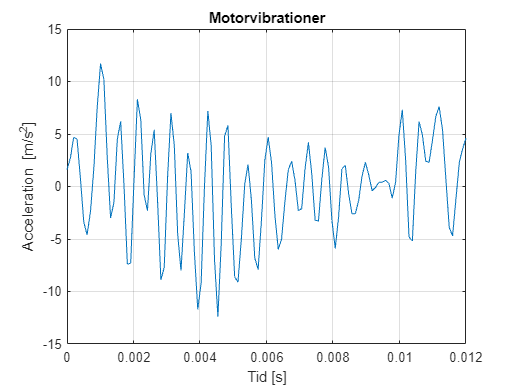



plot(t, a), grid, xlabel("Tid [s]"), ylabel("Acceleration [m/s^2]"), title("Motorvibrationer")

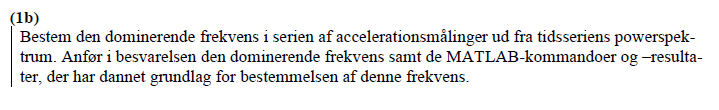

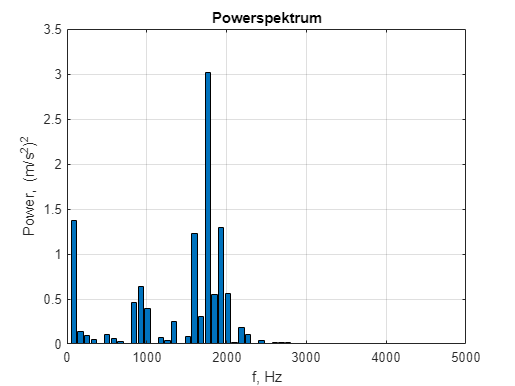

format shortg

T = n*dt;
fmax = f/2;

df = 1/T;

A = fft(a)/n; % FFt af accelerationsdata
P = real(A).^2 + imag(A).^2;    % Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive

f = linspace(0, n*df, n);

bar(f, P), xlim([0, fmax]), grid()

xlabel("f, Hz"), ylabel("Power, (m/s^2)^2"), title("Powerspektrum")



[m, i] = max(P)

m =         3.017


i =     22



dom_f = f(i)

dom_f =        1764.7


Den dominerende frekvens er altså 1764,7Hz

## Opgave 1c)

clear
f = 0:200:5000;

P = [0.00 0.26 0.24 0.65 1.97 0.32 0.04 0.00 0.90 ...
     1.44 3.60 0.08 0.58 0.06 0.09 0.10 0.04 0.06 ...
     0.06 0.05 0.05 0.05 0.05 0.05 0.04 0.05];

N = length(P)

N =     26



fprintf('f, Hz   P, (m/s^2)^2\n')

f, Hz   P, (m/s^2)^2



for i = 2:N-1
  if P(i) > P(i-1) && P(i) > P(i+1)
    fprintf('%5.0f   %6.4f\n',f(i),P(i))
  end
end

  200   0.2600
  800   1.9700
 2000   3.6000
 2400   0.5800
 3000   0.1000


## Opgave 2

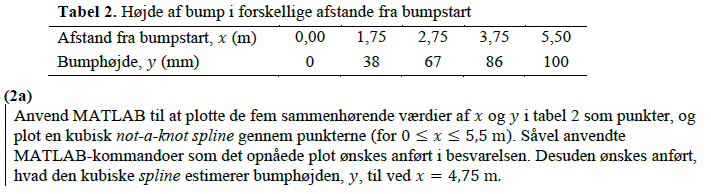

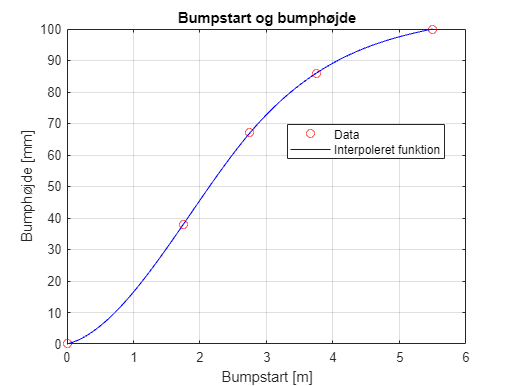

clear % Clear alle foregående variable

d = 5.5; % meter
damp = 50; % km/t

x = [0, 1.75, 2.75, 3.75, 5.5];
y = [0, 38, 67, 86, 100]; % i mm

% Linspace til plot
xlin = linspace(min(x), max(x));

% Not a knot spline oprettes
spl_func = spline(x,y,xlin);

% Data plottes
plot(x,y, 'ro', 'DisplayName', 'Data'), grid("on")
title('Bumpstart og bumphøjde')
xlabel('Bumpstart [m]')
ylabel('Bumphøjde [mm]')

hold on

% Fit plottes
plot(xlin, spl_func,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off


% Find specifik værdi
bump_475mm = spline(x,y, 4.75)

bump_475mm =        95.971


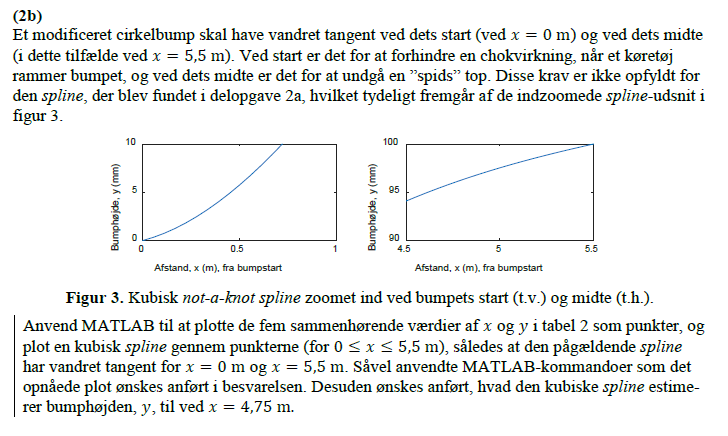

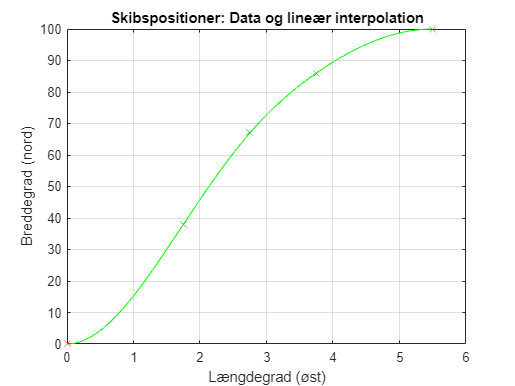

clear % Clear alle foregående variable

d = 5.5; % meter
damp = 50; % km/t

x = [0, 1.75, 2.75, 3.75, 5.5];
y = [0, 38, 67, 86, 100]; % i mm

y_ny = [0, y, 0];

% Linspace
xlin = linspace(min(x), max(x));

% Kubisk fit
x_kub = spline(x, y_ny, xlin); 

plot(x,y,"rx", xlin, x_kub,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid


% Find specifik værdi
bump_475mm = spline(x,y_ny, 4.75)

bump_475mm = 97.1982

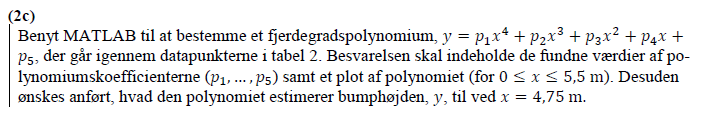

clear

x = [0, 1.75, 2.75, 3.75, 5.5];
y = [0, 38, 67, 86, 100]; % i mm


format short

% Polyfit
n = length(x);

koeff = polyfit(x, y, n-1)';

% Tabbel over værdier
T = table(koeff, x', y', 'VariableNames',{'Koeff', 'Bumplængde', 'Bumphøjde'});
disp(T)

       Koeff       Bumplængde    Bumphøjde
    ___________    __________    _________

        0.41936          0            0   
        -5.4996       1.75           38   
         20.923       2.75           67   
       -0.30693       3.75           86   
    -1.3791e-13        5.5          100   



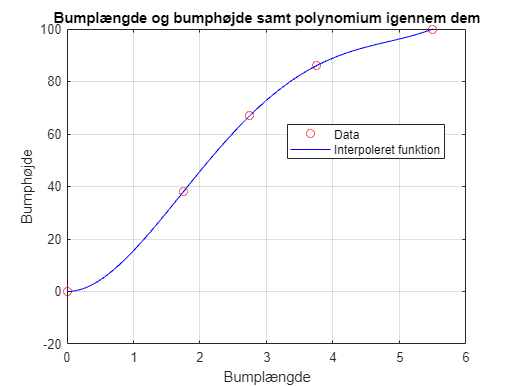


% der plottes for at se hvor godt fittet er

xlin = linspace(min(x), max(x));
ys = polyval(koeff, xlin);

plot(x, y, 'ro', 'DisplayName', 'Data'), grid("on")

title('Bumplængde og bumphøjde samt polynomium igennem dem')
xlabel('Bumplængde'), ylabel('Bumphøjde')

hold on

plot(xlin, ys,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off


bump_475mm = polyval(koeff, 4.75)

bump_475mm = 94.7129

## Opgave 3

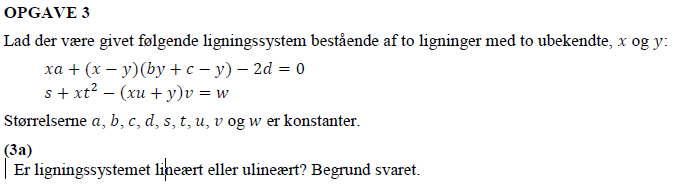

clear

syms a b c d s t u v w x y

l1 = x*a + (x+y) * (b*y+c-y) - 2*d;
l2 = s + x*t^2 - (x*u+y)*v - w;

ls = [l1, l2];
vars = [x,y]

$$vars = \left(\begin{array}{cc} x & y \end{array}\right)$$


J = jacobian(ls, vars)

$$J = \left(\begin{array}{cc} a+c-y+b\,y & c-y+b\,y+\left(x+y\right)\,\left(b-1\right)\\ t^{2}-u\,v & -v \end{array}\right)$$

Det ses systemet er ulinært eftersom de ubekendte indgår i den første række, begge søjler, af jacobi matricen

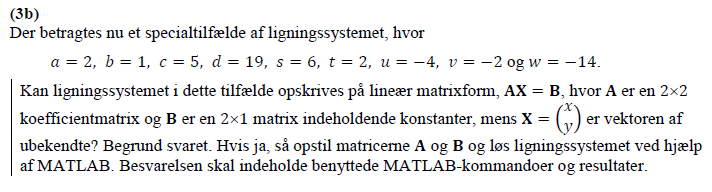

clear

a=2;b=1;c=5;d=19;s=6;t=2;u=-4;v=-2;w=-14;

syms x y

l1 = x*a + (x-y) * (b*y+c-y) - 2*d;
l2 = s + x*t^2 - (x*u+y)*v - w;

ls = [l1; l2]

$$ls = \left(\begin{array}{c} 7\,x-5\,y-38\\ 2\,y-4\,x+20 \end{array}\right)$$

vars = [x; y]

$$vars = \left(\begin{array}{c} x\\ y \end{array}\right)$$


S = solve(ls, vars)

S = struct with fields:
    x: 4
    y: -2



x = vpa(S.x, 3)

$$x = 4.0$$

y = vpa(S.y, 3)

$$y = -2.0$$

En anden måde, som opgaven ønsker:

[A, B] = equationsToMatrix(ls,vars)

$$A = \left(\begin{array}{cc} 7 & -5\\ -4 & 2 \end{array}\right)$$

$$B = \left(\begin{array}{c} 38\\ -20 \end{array}\right)$$


matsol = A\B

$$matsol = \left(\begin{array}{c} 4\\ -2 \end{array}\right)$$


x = matsol(1)

$$x = 4$$

y = matsol(2)

$$y = -2$$

Giver samme resultat

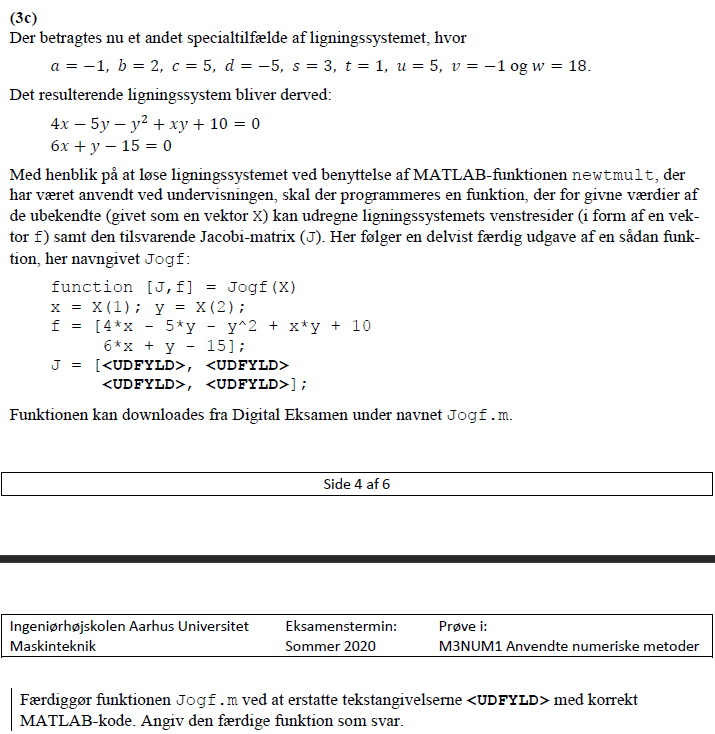

clear

syms x y
f = [4*x - 5*y - y^2 + x*y + 10
     6*x + y - 15]

$$f = \left(\begin{array}{c} 4\,x-5\,y+x\,y-y^{2}+10\\ 6\,x+y-15 \end{array}\right)$$


jacobian(f)

$$ans = \left(\begin{array}{cc} y+4 & x-2\,y-5\\ 6 & 1 \end{array}\right)$$

Den færdige funktion

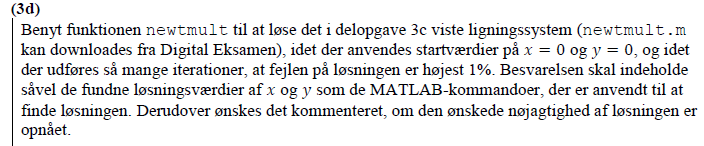

clear
x0 = 0;
y0 = 0;
es = 1; 

conds = [x0; y0];

[x,f,ea,iter] = newtmult(@Jogf,conds ,1)

x =     2.0000
    3.0001


f =    -0.2925
         0


ea = 0.9528

iter = 3

# Funktioner

function [J,f] = Jogf(X)
x = X(1); y = X(2);
f = [4*x - 5*y - y^2 + x*y + 10
     6*x + y - 15];
J = [y + 4, x - 2*y - 5; 6, 1];
end


function [x,f,ea,iter] = newtmult(func,x0,es,maxit)
% newtmult: Newton-Raphson root zeroes nonlinear systems
%   [x,f,ea,iter]=newtmult(func,x0,es,maxit):
%     uses the Newton-Raphson method to find the roots of
%     a system of nonlinear equations
% input:
%   func = name of function that returns f and J
%   x0 = initial guess
%   es = desired percent relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
% output:
%   x = vector of roots
%   f = vector of functions evaluated at roots
%   ea = approximate percent relative error (%)
%   iter = number of iterations
if nargin<2, error('at least 2 input arguments required'), end
if nargin<3 || isempty(es), es = 0.0001; end
if nargin<4 || isempty(maxit), maxit = 50; end
iter = 0;
x = x0;
while 1
  [J,f] = func(x);
  dx = J\f;
  x = x-dx;
  iter = iter + 1;
  ea = 100*max(abs(dx./x));
  if iter>=maxit || ea<=es, break, end
end
end










